# 离散路径点航向角与曲率计算示例

## 以一条三次多项式曲线为例

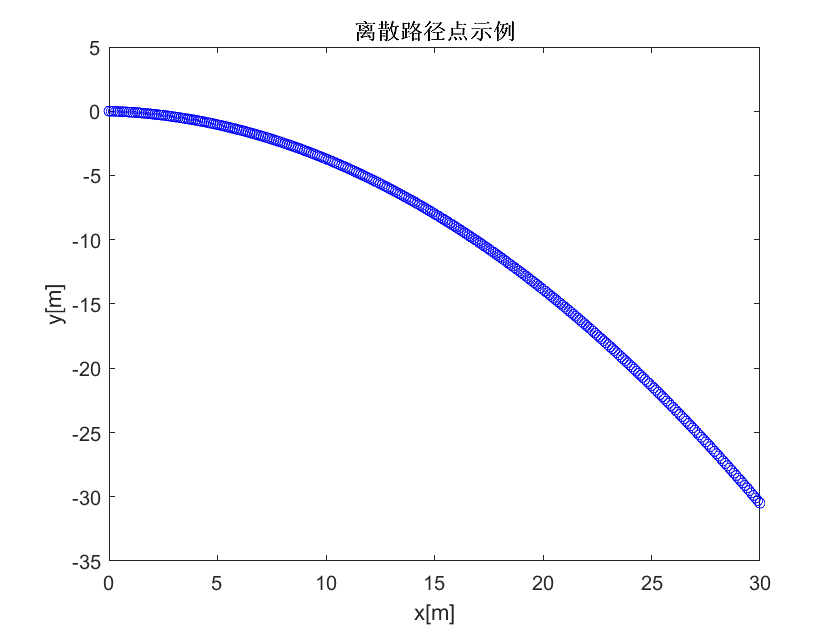

clearvars;
close all;
x = transpose(0 : 0.1 : 30);
y = -4.32e-6 * x.^3 - 3.21e-2 * x.^2 - 5e-2 * x + 1e-2;
yaw_angle = zeros(size(x));
example_path = [x, y, yaw_angle];
figure;
plot(x, y, 'bo', 'MarkerSize', 5);
xlabel('x[m]');
ylabel('y[m]');
title('离散路径点示例');

## 路点航向角计算过程

`    保持起点、终点的角度不变，中间点则是以每点前后两点连线方向与``x``轴正向的夹角作为该点的航向角，逆时针方向为正，见图1。`

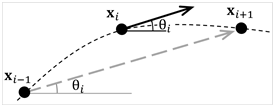

`图1`  `路点航向角计算示意`

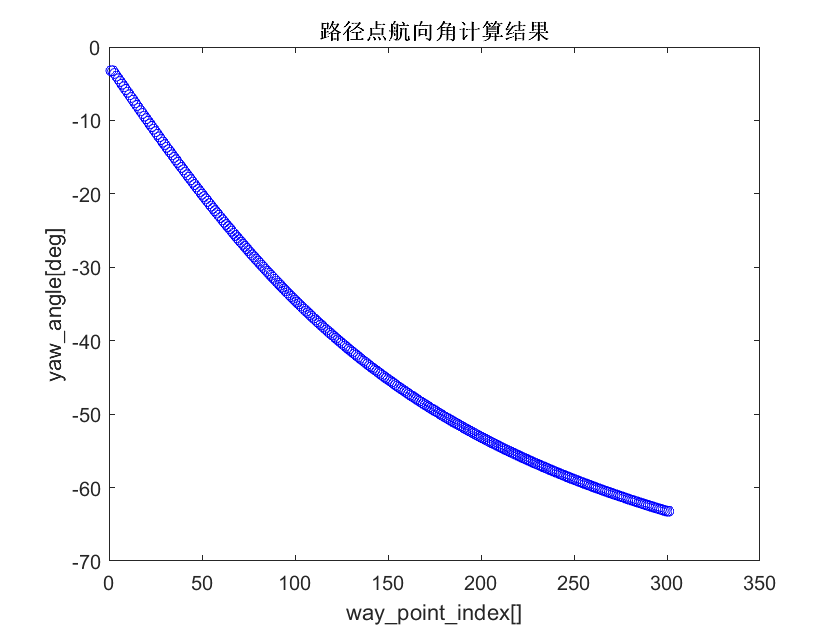

% 首尾两点分别采用第2点、倒数第2点的航向角数值
for index = 2 : size(example_path, 1) - 1
    delta_y = example_path(index + 1, 2) - example_path(index - 1, 2);
    delta_x = example_path(index + 1, 1) - example_path(index - 1, 1);
    example_path(index, 3) = atan2(delta_y, delta_x);
end
example_path(1, 3) = example_path(2, 3);
example_path(end, 3) = example_path(end - 1, 3);

% 绘图查看计算得到的路径点航向角
figure;
plot(rad2deg(example_path(:, 3)), 'bo', 'MarkerSize', 5);
xlabel('way\_point\_index[]');
ylabel('yaw\_angle[deg]');
title('路径点航向角计算结果');

## 路点曲率计算过程

`    采用两点的角度偏差除以间隔距离近似计算曲率，通常得到的曲率变化不够平滑，可以再通过滑动平均对数值方法计算得到的曲率做进一步的平滑。`

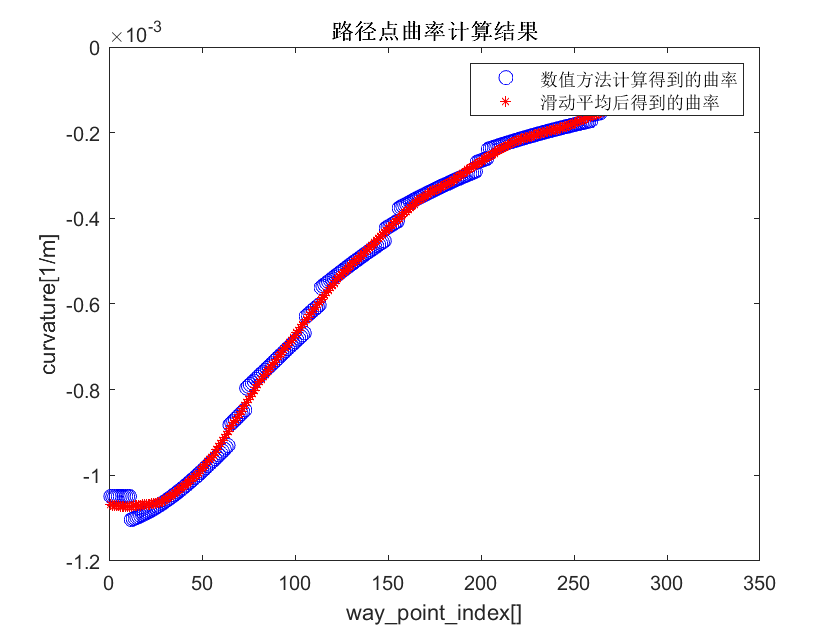

% 通过数值方法算得曲率
numerical_curvature = Curvature_calculate(example_path);

% 设定曲率滑动平均窗口宽度
curvature_move_mean_width = 35;

% 滑动平均
processed_curvature = movmean(numerical_curvature, curvature_move_mean_width);

% 绘图查看计算得到的路径点曲率
figure;
plot(numerical_curvature, 'bo', 'MarkerSize', 7);
hold on;
plot(processed_curvature, 'r*', 'MarkerSize', 5);
legend('数值方法计算得到的曲率', '滑动平均后得到的曲率');
xlabel('way\_point\_index[]');
ylabel('curvature[1/m]');
title('路径点曲率计算结果');